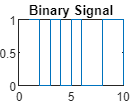


%---- VARIABLES TO CHANGE ----%
signal_length = 10;   % number of data bits
M = 8;                 % samples per bit (chips per bit)
init = [1 1 1 1 1 0 1];% 7-stage 
taps = [1 4 7];          % feedback taps first, fourth and seventh bit's of init


%--------------------- MAIN -------------------------%

%--- BINARY DATA INPUT SIGNAL ---%
binary_signal = binary_data_gen(signal_length);
figure;stairs(binary_signal);title('Binary Signal');

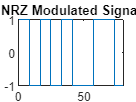



%--- NRZ MODULATION ---%
mod_signal = modulator(M,binary_signal);
figure;stairs(mod_signal);title('NRZ Modulated Signal');

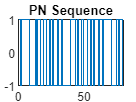


%--- PN SEQUENCE ---%
pn = pn_sequence_lfsr(signal_length, M, init, taps);
figure; stairs(pn); title('PN Sequence');

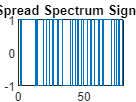


%--- SPREAD SIGNAL (NRZ * PN SEQ.) ---%
spread_signal = mod_signal .* pn;
figure; stairs(spread_signal); title('Spread Spectrum Signal');

function binary_signal = binary_data_gen(signal_length)  % INPUT SIGNAL
    binary_signal = randi([0, 1],1, signal_length);
end

function mod_signal = modulator(M, binary_signal) % MODULATED NRZ SIGNAL BY M
    y_bin = (2 * binary_signal - 1);
    mod_signal = repelem(y_bin, M);
end


function pn = pn_sequence_lfsr(num_bits, chips_per_bit, init, taps) % PN GENERATOR LFSR METHOD
    if all(init == 0), error('init state must be nonzero.'); end
    N = num_bits * chips_per_bit;
    reg = logical(init(:).');
    chips01 = false(1, N);
    for k = 1:N
        out_bit = reg(end);
        chips01(k) = out_bit;
        fb = mod(sum(reg(taps)), 2);
        reg = [logical(fb) reg(1:end-1)];
    end
    pn = 2*double(chips01) - 1;
end
